# Assignment 2: Digital Modulation and Demodulation

clearvars; clc;

## Activity 4

Rectangular pulse

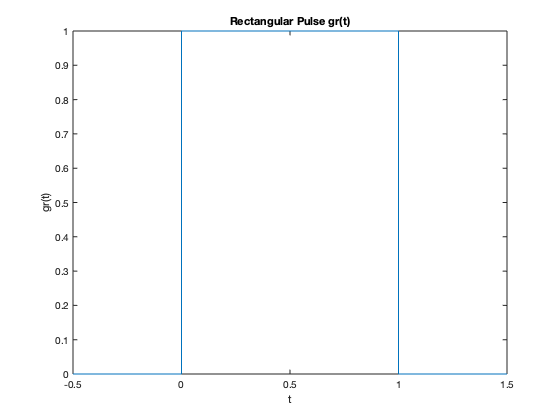

%% A
%(a)
syms t w
A = 1;
T = 1;
gr = A * rectangularPulse(0,T,t);
figure(1)
fplot(gr,[-0.5 1.5])
title("Rectangular Pulse gr(t)")
xlabel('t')
ylabel('gr(t)')


%(b)
Gr = fourier(gr);
pretty(simplify(Gr))

cos(w) 1i + sin(w) - i
----------------------
           w



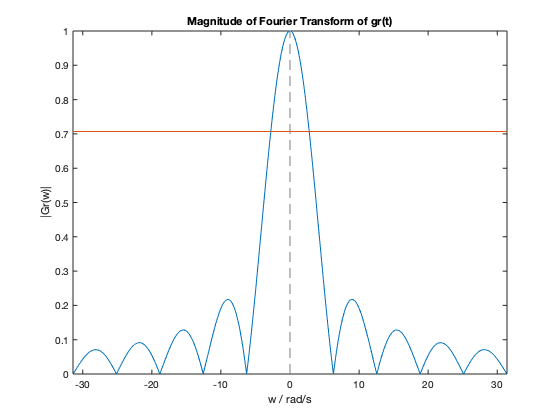

figure(2)
fplot(abs(Gr),[-10*pi 10*pi])
hold on 
fplot(sqrt(2)/2,[-10*pi 10*pi])
hold off
title("Magnitude of Fourier Transform of gr(t)")
xlabel('w / rad/s')
ylabel('|Gr(w)|')
ylim([0 1])

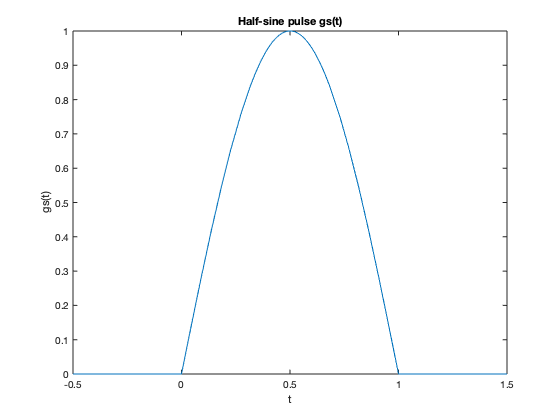


%% B
%(a)
syms t w
A = 1;
T = 1;
gs = A*sin(pi*t/T) * rectangularPulse(0,T,t);
figure(3)
fplot(gs,[-0.5 1.5])
title("Half-sine pulse gs(t)")
xlabel('t')
ylabel('gs(t)')


%(b)
Gs = fourier(gs);
pretty(simplify(Gs))

pi (cos(w) + 1 - sin(w) 1i)
---------------------------
            2     2
         - w  + pi



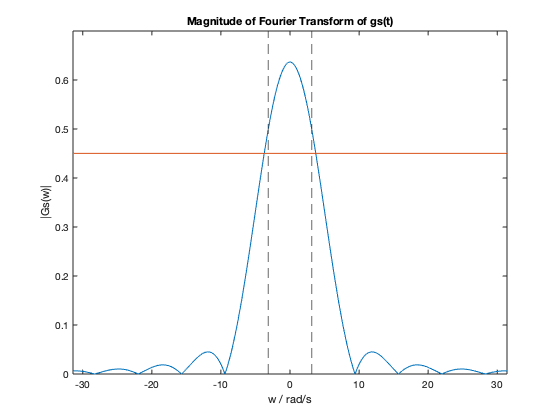

figure(4)
fplot(abs(Gs),[-10*pi -pi],'Color',[0 0.4470 0.7410])
hold on
fplot(abs(Gs),[-pi pi],'Color',[0 0.4470 0.7410])
hold on
fplot(abs(Gs),[pi 10*pi],'Color',[0 0.4470 0.7410])
hold on
fplot(sqrt(2)/2*2/pi,[-10*pi 10*pi],'Color',[0.8500 0.3250 0.0980])
hold on
xline(-pi,'--');
hold on
xline(pi,'--');
hold off
title("Magnitude of Fourier Transform of gs(t)")
xlabel('w / rad/s')
ylabel('|Gs(w)|')
ylim([0 0.7])

## Activity 5

Raised-cosine pulse

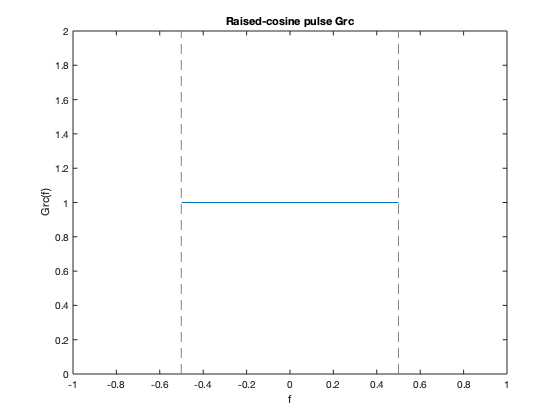

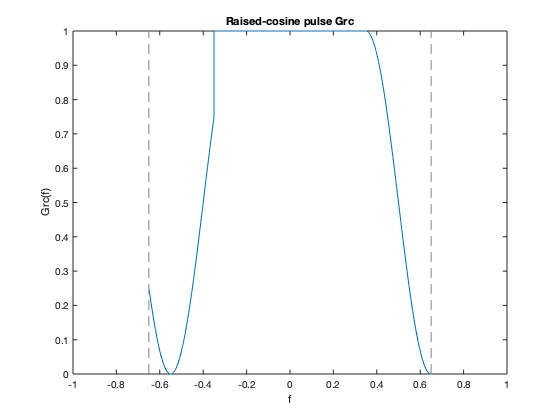

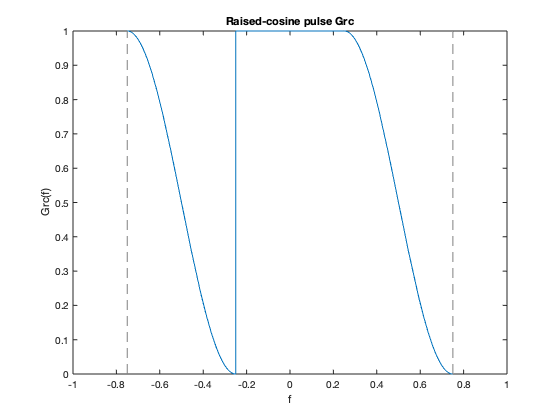

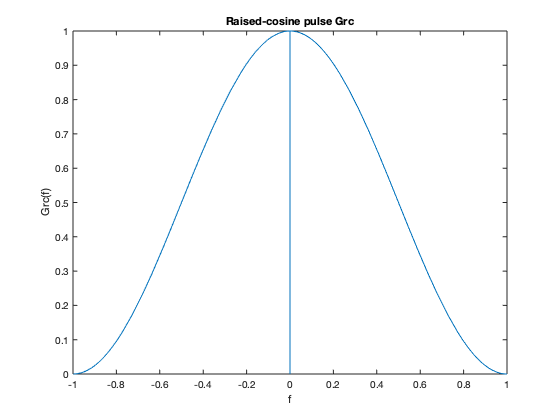

syms f
beta = [0 0.3 0.5 1];
T = 1;
for i = 1:4
    Grc = piecewise(abs(f)<(1-beta(i))/2/T, T, (1-beta(i))/2/T<abs(f)<(1+beta(i))/2/T, T/2*(1+cos(pi*T/beta(i)*(f-(1-beta(i))/2/T))),abs(f)<(1+beta(i))/2/T,0);
    figure(i+4)
    fplot(Grc,[-1 1])
    title("Raised-cosine pulse Grc")
    xlabel('f')
    ylabel('Grc(f)')
end

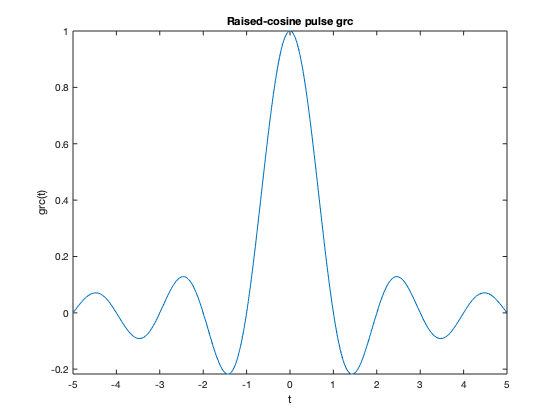

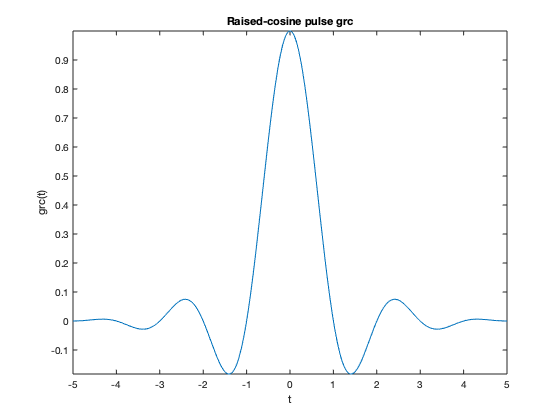

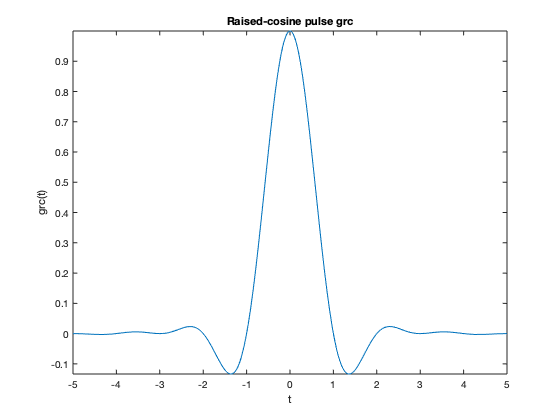

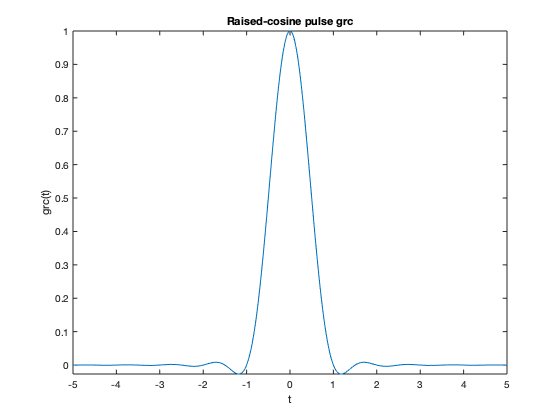


syms t
beta = [0 0.3 0.5 1];
T = 1;
for i = 1:4
    grc = piecewise(abs(t) == T/2*beta(i), pi/4/T*sinc(1/2/beta(i)), abs(t) ~= T/2*beta(i), 1/T*sinc(t/T)*cos(pi*beta(i)*t/T)/(1-(2*beta(i)*t/T)^2));
    figure(i+8)
    fplot(grc,[-5 5])
    title("Raised-cosine pulse grc")
    xlabel('t')
    ylabel('grc(t)')
end

## Activity 6

Root-raised-cosine pulse

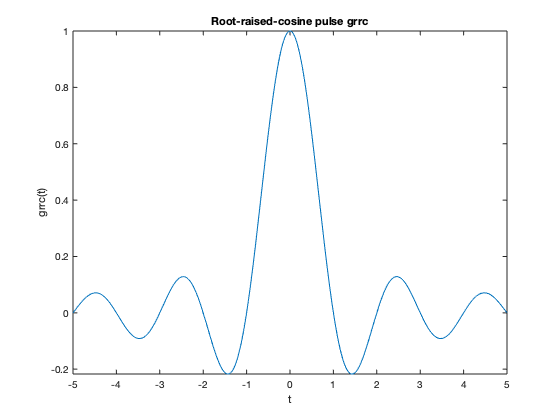

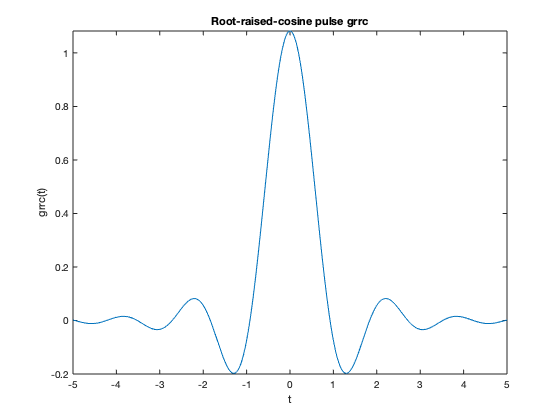

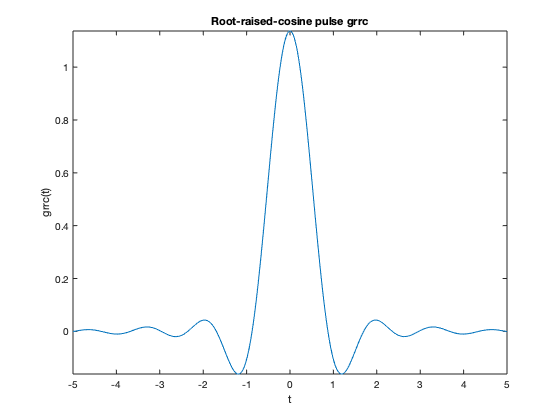

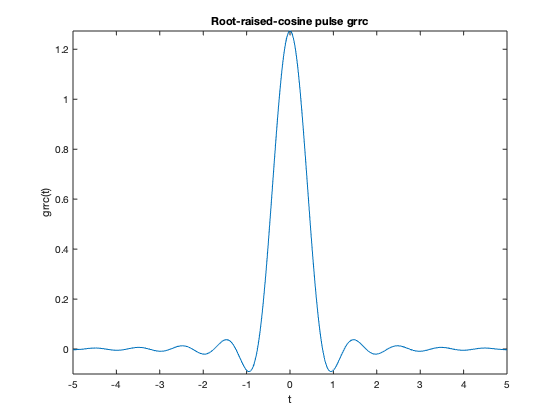

syms t
beta = [0 0.3 0.5 1];
T = 1;
for i = 1:4
    grrc = piecewise(abs(t) == 0, (1+beta(i)*(4/pi-1))/T, abs(t) == T/4*beta(i), beta(i)/sqrt(2)/T*((1+2/pi)*sin(pi/4/beta(i))+(1-2/pi)*cos(pi/4/beta(i))), (abs(t) ~= T/2*beta(i))&(abs(t) ~= 0), (sin(pi*t/T*(1-beta(i)))+4*beta(i)*t/T*cos(pi*t/T*(1+beta(i))))/pi/t/(1-(4*beta(i)*t/T)^2)/T);
    figure(i+12)
    fplot(grrc,[-5 5])
    title("Root-raised-cosine pulse grrc")
    xlabel('t')
    ylabel('grrc(t)')
end

## Activity 7

Test script for the function qpsk_mod(). Carrier frequency 5Hz. Oversampling factor 16.

b_in = [0,1,1,0,1,1,0,0]            % input bit sequence

b_in =      0     1     1     0     1     1     0     0


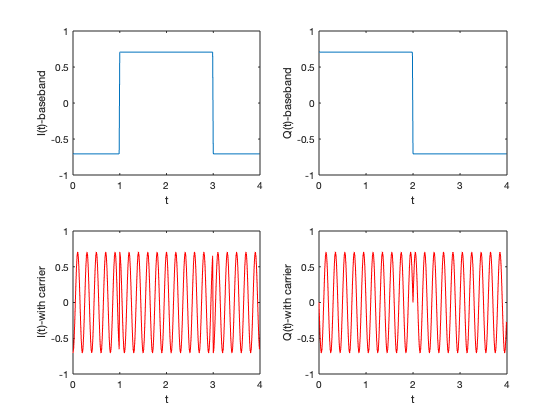

[t, I, Q, IChannel, QChannel] = qpsk_mod(b_in, 5, 16);

figure(17);

% baseband I(t)
subplot(2,2,1);
plot(t, I);
xlabel('t');
ylabel('I(t)-baseband');

% baseband Q(t)
subplot(2,2,2);
plot(t, Q);
xlabel('t');
ylabel('Q(t)-baseband');

% I(t) with carrier
subplot(2,2,3);
plot(t, IChannel, 'r');
xlabel('t'); ylabel('I(t)-with carrier');

% Q(t) with carrier
subplot(2,2,4);
plot(t, QChannel, 'r');
xlabel('t'); ylabel('Q(t)-with carrier');

## Activity 11

Test script for the function qpsk_demod(). Carrier frequency 5Hz. Oversampling factor 16.

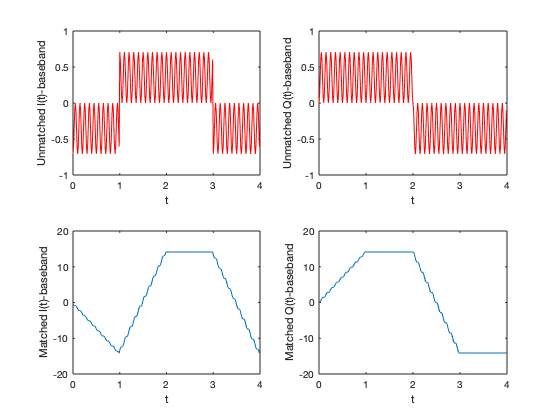

[t, b_out, I_unmatched, Q_unmatched, ...
    I_matched, Q_matched] = qpsk_demod(IChannel, QChannel, 5, 16);

figure;

% unmatched I(t)
subplot(2,2,1); plot(t, I_unmatched, 'r');
xlabel('t'); ylabel('Unmatched I(t)-baseband');

% unmatched Q(t)
subplot(2,2,2); plot(t, Q_unmatched, 'r');
xlabel('t'); ylabel('Unmatched Q(t)-baseband');

% matched I(t)
subplot(2,2,3); plot(t, I_matched(1:length(t)));
xlabel('t'); ylabel('Matched I(t)-baseband');
axis([0 4 -20 20])

% matched Q(t)
subplot(2,2,4); plot(t, Q_matched(1:length(t)));
xlabel('t'); ylabel('Matched Q(t)-baseband');
axis([0 4 -20 20])


b_in

b_in =      0     1     1     0     1     1     0     0


b_out

b_out =      0     1     1     0     1     1     0     0


## Assignment 2 PART A

End-to-end simulation.

N = 10000;          % Number of symbols to transmit
EbN0dB = -4:2:10;   % Eb/N0 range in dB for simulation
L = 8;              % oversampling factor
Fc = 100;           % carrier frequency
Fs = L*Fc;          % sampling frequency

BER = zeros(1,length(EbN0dB));  % BER values for each Eb/N0
EbN0lin = 10.^(EbN0dB/10); 
EsN0lin = EbN0lin*log2(4);
EsN0dB = log10(EsN0lin)*10;

b_in = randi([0,1],1,2*N);
k = length(b_in);
[t, I, Q, IChannel, QChannel] = qpsk_mod(b_in, Fc, L);
n = length(IChannel);
M = 4;
codeRate = k/n;
CodedEbN0dB = EbN0dB + 10*log10(k/n);

CodedSNR = CodedEbN0dB + 20*log10(log2(M));

for i = 1:length(EbN0dB)

    INChannel = awgn(IChannel,CodedSNR(i));
    QNChannel = awgn(QChannel,CodedSNR(i));
    
    [tt, b_out, I_unmatched, Q_unmatched, ...
        I_matched, Q_matched] = qpsk_demod(INChannel, QNChannel, Fc, L);

    m(i) = length(find(b_out ~= b_in));
end

Ber_posterior = m./length(b_in)

Ber_posterior =     0.2490    0.1721    0.1162    0.0578    0.0180    0.0039    0.0004         0


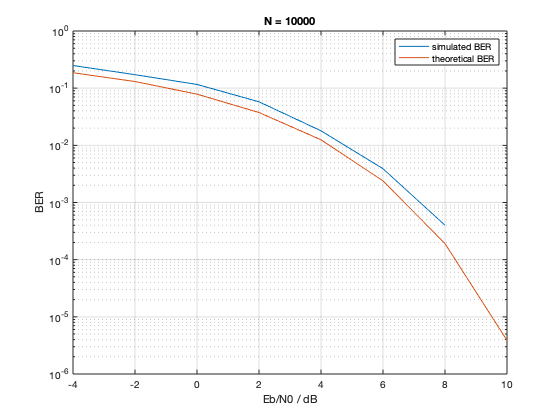

Ber_theoretical = berawgn(EbN0dB,'psk',M,'nondiff');

figure
semilogy(EbN0dB,Ber_posterior,EbN0dB,Ber_theoretical);
grid on
legend('simulated BER','theoretical BER')
xlabel('Eb/N0 / dB')
ylabel('BER')
title('N = 10000')

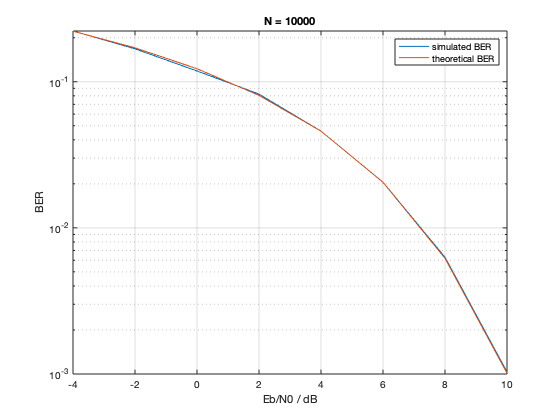



M = 8; 
N0 = 1;
Es = log2(M)*N0*EbN0lin;
    
for n = 1:N
    ber = zeros(1,length(EbN0dB)); 
    for i = 1:length(Es)
        r1 = sqrt(Es(i)) + sqrt(N0/2) * randn;
        r2 = sqrt(N0/2) * randn;
        if (r1 > 0 && abs(atan(r2/r1)) <= pi/8) 
            ber(i) =  ber(i) + 0;
        else if (r1 < 0 && (pi/8 <= atan(r2/r1) <= 3*pi/8))
                ber(i) =  ber(i) + 3/3;
             else if (pi/8 <= abs(atan(r2/r1)) <= 3*pi/8)
                      ber(i) =  ber(i) + 1/3;
                  else ber(i) =  ber(i) + 2/3;
                  end
             end
        end
    end
    BER = BER + ber;
end
BER_posterior = BER/N;

BER_theoretical = berawgn(EbN0dB,'psk',M,'nondiff');

figure
semilogy(EbN0dB,BER_posterior,EbN0dB,BER_theoretical);
grid on
legend('simulated BER','theoretical BER')
xlabel('Eb/N0 / dB')
ylabel('BER')
title('N = 10000')

## Functions

Implementation of QPSK modulator

function [t, I, Q, IChannel, QChannel] = qpsk_mod(b, fc, L)
% Function to modulate an incoming binary stream using conventional QPSK
% b - input binary data stream (1D array of 0s and 1s)
% fc - carrier frequency (Hz)
% L - upsampling factor
% t - time vector for the carrier modulated signal
% I - unmodulated I channel (no carrier)
% Q - unmodulated Q channel (no carrier)
% IChannel - carrier modulated I channel
% QChannel - carrier modulated Q channel

I = [];
Q = [];
II = 0;
QQ = 0;

assert(mod(length(b), 2) == 0, 'Input should have even number of bits.');

% parameters
fs = L * fc;    % sampling frequency
t=0: 1/fs : (length(b)/2*fs-1)/fs; %time vector

% unmodulated I and Q streams
Iu = b(1:2:length(b)-1);
Qu = b(2:2:length(b));

% LUT, gray code
% approx. 1 line of code
bg = bin2gray(Iu*2+Qu,'psk',4);

% serial-to-parralle
for idx = 1:2:length(b)
    % bit packing, use bitset function
    % approx. 2 lines of code
    b(idx) = bitset(b(idx),2,b(idx));
    bp = bitset(b(idx),1,b(idx+1));
    
    % symbol mapping
    % approx. 1 line of code
    sm = ((bg((idx+1)/2) >= 2) + (rem(bg((idx+1)/2),2) == 1) * 1i)/sqrt(2);
    
    % real/imag splitter
    % approx. 2 lines of code
    i = (2*sqrt(2)*real(sm)-1)/sqrt(2);
    q = (2*sqrt(2)*imag(sm)-1)/sqrt(2);
    
    % in-phase (I) and quadrature (Q) stream
    % upsampling by L
    % approx. 2 lines of code
    ius = upsample(i,fs);
    qus = upsample(q,fs);
    
    % append to unmodulated I and Q streams
    % approx. 2 lines of code
    I = [I;ius];
    Q = [Q;qus];
end

% serialize I and Q
I = I(:).';
Q = Q(:).';

% rectangular pulse shaping, be careful of the output length
% approx. 5 lines of code

F = ones(1,fs);
I = filter(F,1,I);
Q = filter(F,1,Q);

% mixed with carrier
% approx. 2 lines of code

IChannel = I .* cos(2*pi*fc*t);
QChannel = Q .* (-sin(2*pi*fc*t));

end

Implementation of QPSK demodulator

function [t, b, I_unmatched, Q_unmatched, ...
    I_matched, Q_matched] = qpsk_demod(IChannel, QChannel, fc, L)
% Function to demodulate a conventional QPSK signal
% r - received signal at the receiver front end
% b - recovered binary data stream (1D array of 0s and 1s)
% fc - carrier frequency (Hz)
% L - upsampling factor (multiples of fc)
% t - time vector for the carrier modulated signal
% I/Q_unmatched - signals before matched filter
% I/Q_matched - signals after matched filter

% parameters
fs = L * fc;    % sampling frequency
t=0: 1/fs : (length(IChannel)-1)/fs; %time vector
b = [];
I_matched = [];
Q_matched = [];

% unmodulate I and Q streams
% approx. 2 lines of code
I_unmatched = IChannel .* cos(2*pi*fc*t);
Q_unmatched = QChannel .* (-sin(2*pi*fc*t));

% matched filtering
% approx. 3 lines of code
F = ones(1,fs);
I_matched = filter(fliplr(F),1,I_unmatched);
Q_matched = filter(fliplr(F),1,Q_unmatched);
% sample at every symbol instant and normalise outputs
% approx. 4 lines of code
Es = length(t)/fs/2;
I_matched = I_matched/Es;
Q_matched = Q_matched/Es;

I_down = downsample(I_matched,fs,fs-1);
Q_down = downsample(Q_matched,fs,fs-1);

% zip I and Q into symbols
sym = complex(I_down, Q_down);

% symbol detection
% approx. 5 lines of code

for i = 1:length(sym)
    b1(i) = real(sym(i))>0;
    b2(i) = imag(sym(i))>0;
end
b = [b1 b2];
lb = length(b);

b = gray2bin(b1*2+b2,'psk',4);

b = reshape(de2bi(b,'left-msb')',1,lb);


end